% Define initial conditions
x0 = 0; % Initial x position
y0 = 0; % Initial y position
z0 = 0; % Initial z position
vx0 = 0; % Initial x velocity
vy0 = 0; % Initial y velocity
vz0 = 0; % Initial z velocity

% Define time range for simulation
t0 = 0; % Start time
tf = 560; % End time
dt = 1; % Time step
t = t0:dt:tf; % Time range for simulation

% Solve differential equations using ode45
y_0 = [x0, y0, z0, vx0, vy0, vz0]; % Initial conditions

[t, y] = ode45(@rocketDynamics, t, y_0);

% Continuous visualization of trajectory
clf
comet3(y(:,1), y(:,2), y(:,3)); % Position in 3D space
title("Continuous visualization of trajectory")
xlabel('x');
ylabel('y');
zlabel('z');
grid on
hold off 
clf

% Discrete visualization of trajectory
clf

x = length(y);

for i = 2:x
 
    plot3(y(i,1), y(i,2), y(i,3),'blacko','LineWidth',2);
    hold on
    plot3(y(i-1,1), y(i-1,2), y(i-1,3),'r-o','LineWidth',2);
    title("Discrete visualization of trajectory")
    hold on 
    grid on
    xlabel('x');
    ylabel('y');
    zlabel('z');
    pause(0.1)
    
end

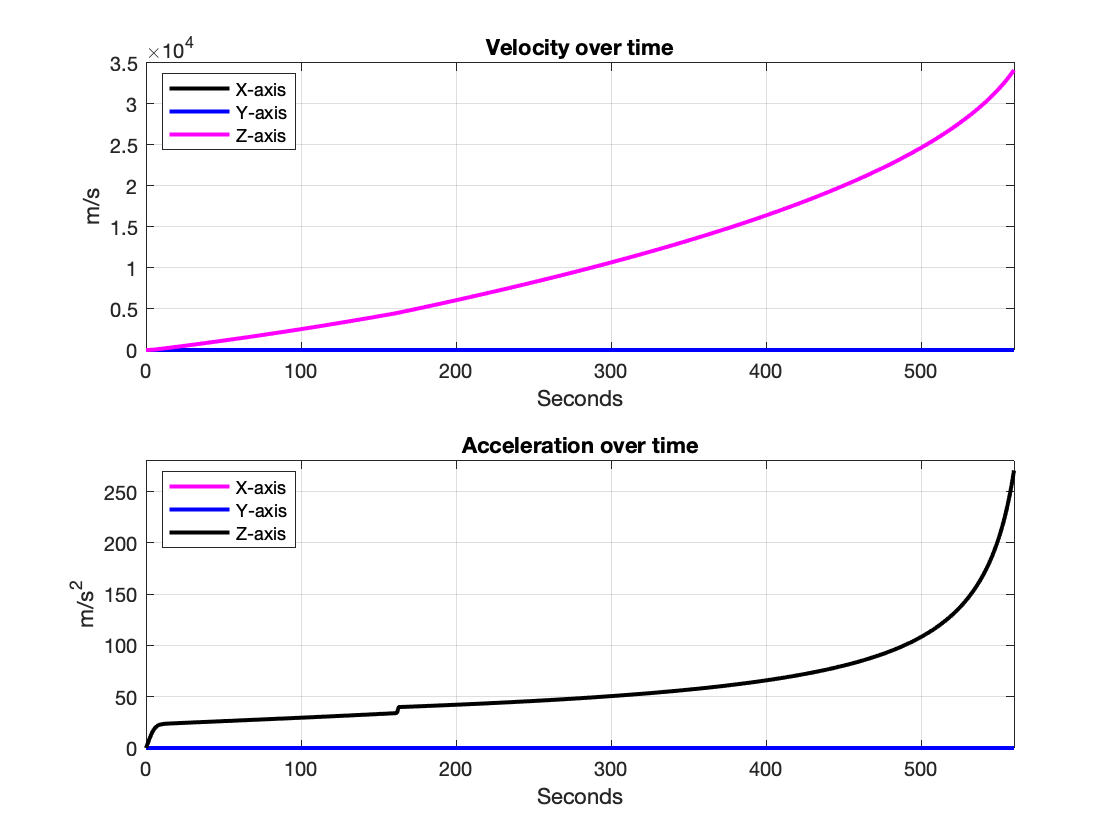

% Velocity plot
clf 

subplot(2,1,1)
plot(t,y(:,1),'black','LineWidth',2);
xlabel("Seconds")
ylabel("m/s")
title("Velocity over time")
grid on
hold on 
ylim([0,(3.5*10^4)]); 
xlim([0,560]); 
plot(t,y(:,2),'blue','LineWidth',2);
plot(t,y(:,3),'m','LineWidth',2);
legend("X-axis","Y-axis","Z-axis")
legend('Location','northwest')
hold off 

% Acceleration plot 
subplot(2,1,2)
plot(t,y(:,4),'m','LineWidth',2)
xlabel("Seconds")
ylabel("m/s^2")
title("Acceleration over time")
hold on
grid on
ylim([0,280]); 
xlim([0,560]); 
plot(t,y(:,5),'blue','LineWidth',2)
plot(t,y(:,6),'black','LineWidth',2)
legend("X-axis","Y-axis","Z-axis")
legend('Location','northwest')
hold off

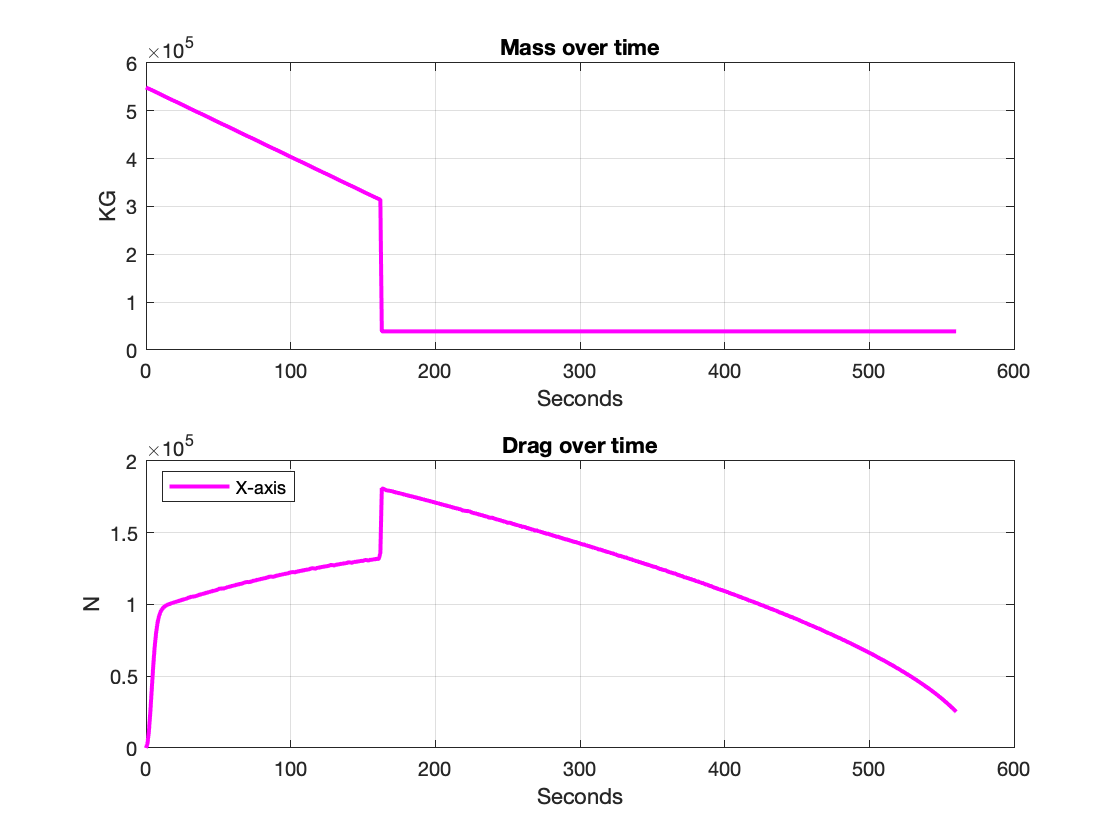


% load('rocket.mat','Fdrag','m','rho');
clf

subplot(2,1,1)
x = zeros(1,561);

for i=1:length(x)
    x(1,i) = mass(t(i));
end

% Mass plot 
plot(t,x,'m','LineWidth',2)

xlabel("Seconds")
ylabel("KG")
title("Mass over time")
hold on
grid on
plot(t,Fdrag,'blue','LineWidth',2)
hold off

subplot(2,1,2)
q = zeros(1,561);

for i=1:length(q)
    q(1,i) = air(y(i,:));
end

plot(t,q,'m','LineWidth',2)
xlabel("Seconds")
ylabel("N")
title("Drag over time")
hold on
grid on
plot(t,m,'blue','LineWidth',2)
legend("X-axis")
legend('Location','northwest')
hold off

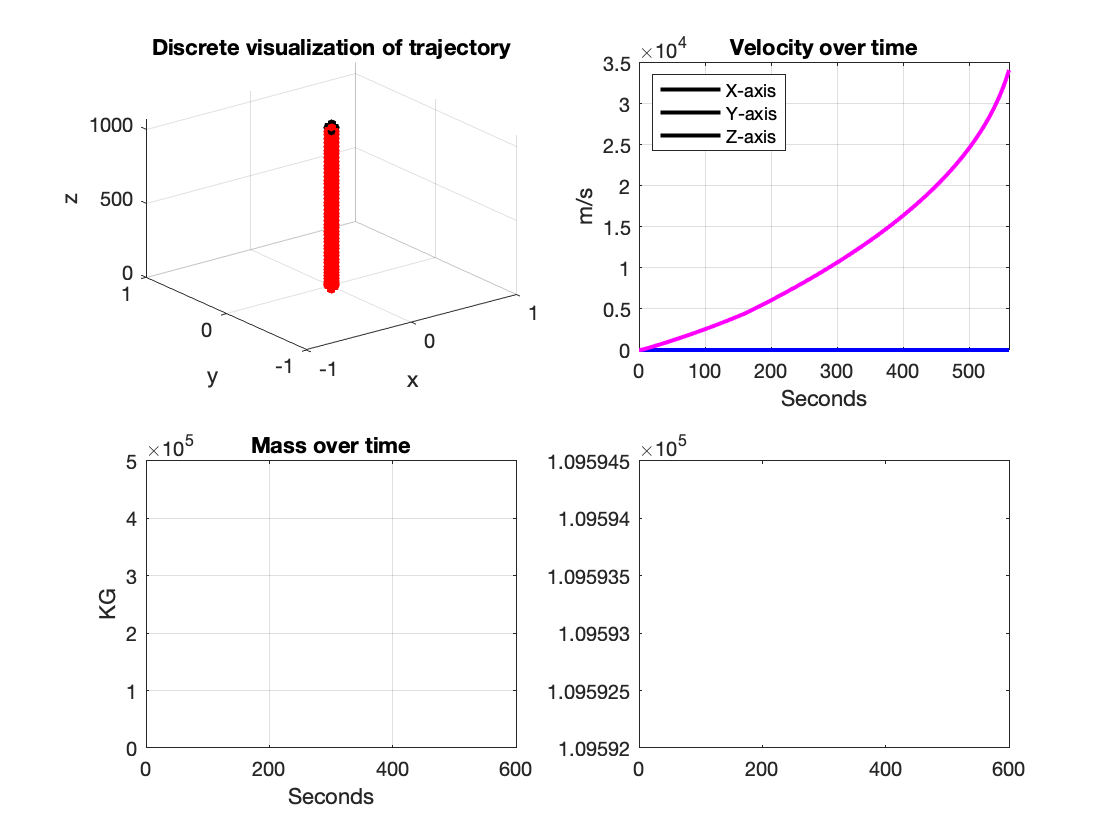

% Animiate all graphs simultaneously

clf

for i = 2:length(y)
 
    subplot(2,2,1)
    plot3(y(i,1), y(i,2), y(i,3),'blacko','LineWidth',2);
    hold on
    plot3(y(i-1,1), y(i-1,2), y(i-1,3),'r-o','LineWidth',2);
    title("Discrete visualization of trajectory")
    hold on 
    grid on
    xlabel('x');
    ylabel('y');
    zlabel('z');
    pause(0.1)
    
    subplot(2,2,2)
    plot(t,y(i,1),'black','LineWidth',2);
    xlabel("Seconds")
    ylabel("m/s")
    title("Velocity over time")
    grid on
    hold on 
    ylim([0,(3.5*10^4)]); 
    xlim([0,560]); 
    plot(t,y(:,2),'blue','LineWidth',2);
    plot(t,y(:,3),'m','LineWidth',2);
    legend("X-axis","Y-axis","Z-axis")
    legend('Location','northwest')
    hold off 

    subplot(2,2,3)
    plot(t,y(i,4),'m','LineWidth',2)
    xlabel("Seconds")
    ylabel("m/s^2")
    title("Acceleration over time")
    hold on
    grid on
    ylim([0,280]); 
    xlim([0,560]); 
    plot(t,y(:,5),'blue','LineWidth',2)
    plot(t,y(:,6),'black','LineWidth',2)
    legend("X-axis","Y-axis","Z-axis")
    legend('Location','northwest')
    hold off

    plot(t,x(i),'m','LineWidth',2)
    
    xlabel("Seconds")
    ylabel("KG")
    title("Mass over time")
    hold on
    grid on
    plot(t,Fdrag,'blue','LineWidth',2)
    hold off
    
    subplot(2,2,4)
    
    plot(t,q(i),'m','LineWidth',2)
    xlabel("Seconds")
    ylabel("N")
    title("Drag over time")
    hold on
    grid on
    plot(t,m,'blue','LineWidth',2)
    legend("X-axis")
    legend('Location','northwest')
    hold off

end